# LAB 07

## Name: Muhammad Asad Imran Rafique

## Student ID: 48065145

## TASK 1

**DSB-SC Single Tone**

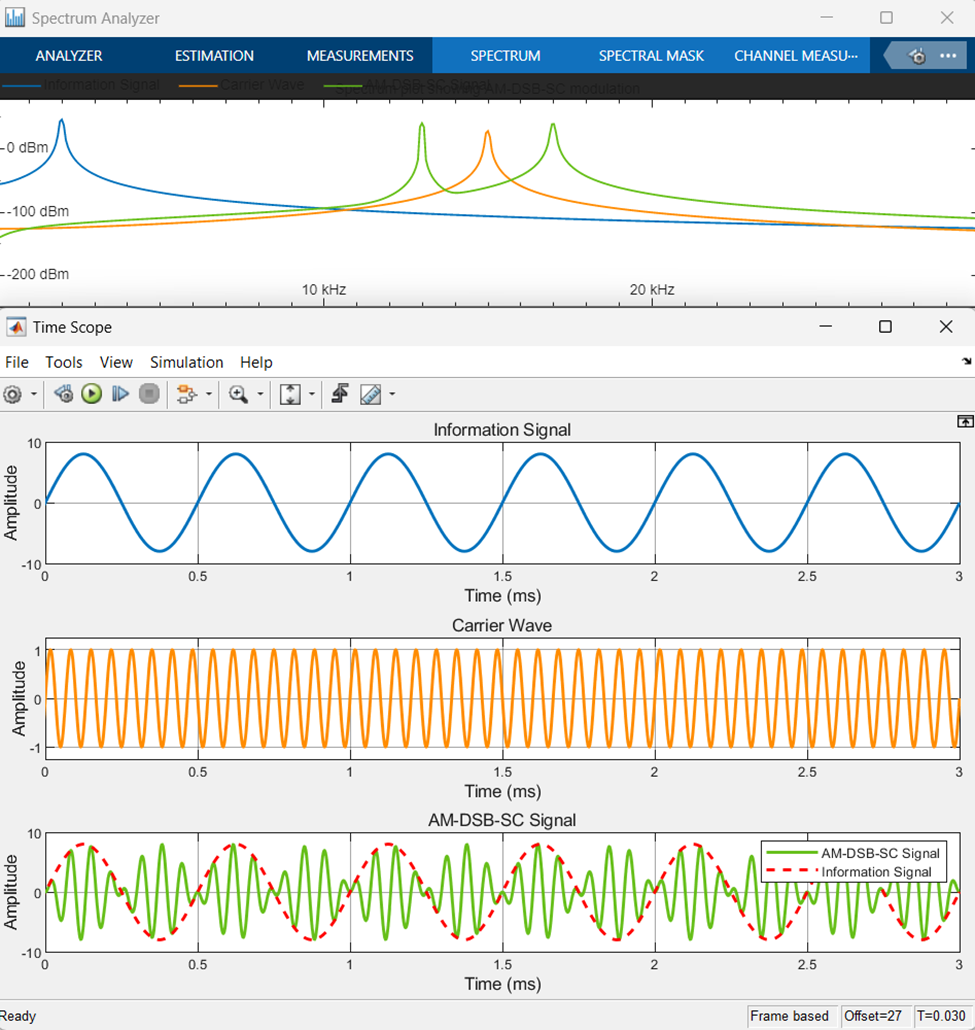

**DSB-SC Sum of Sinusoids**

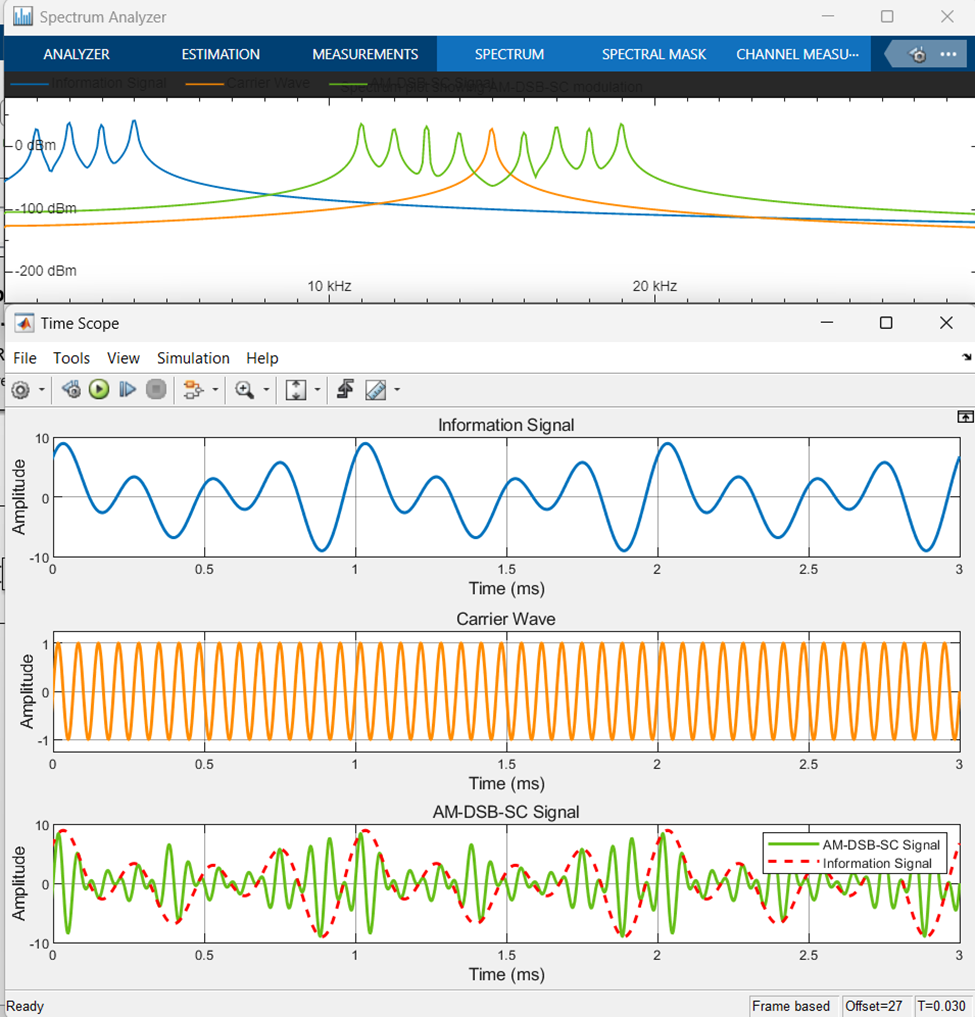

**DSB-TC Single Tone**

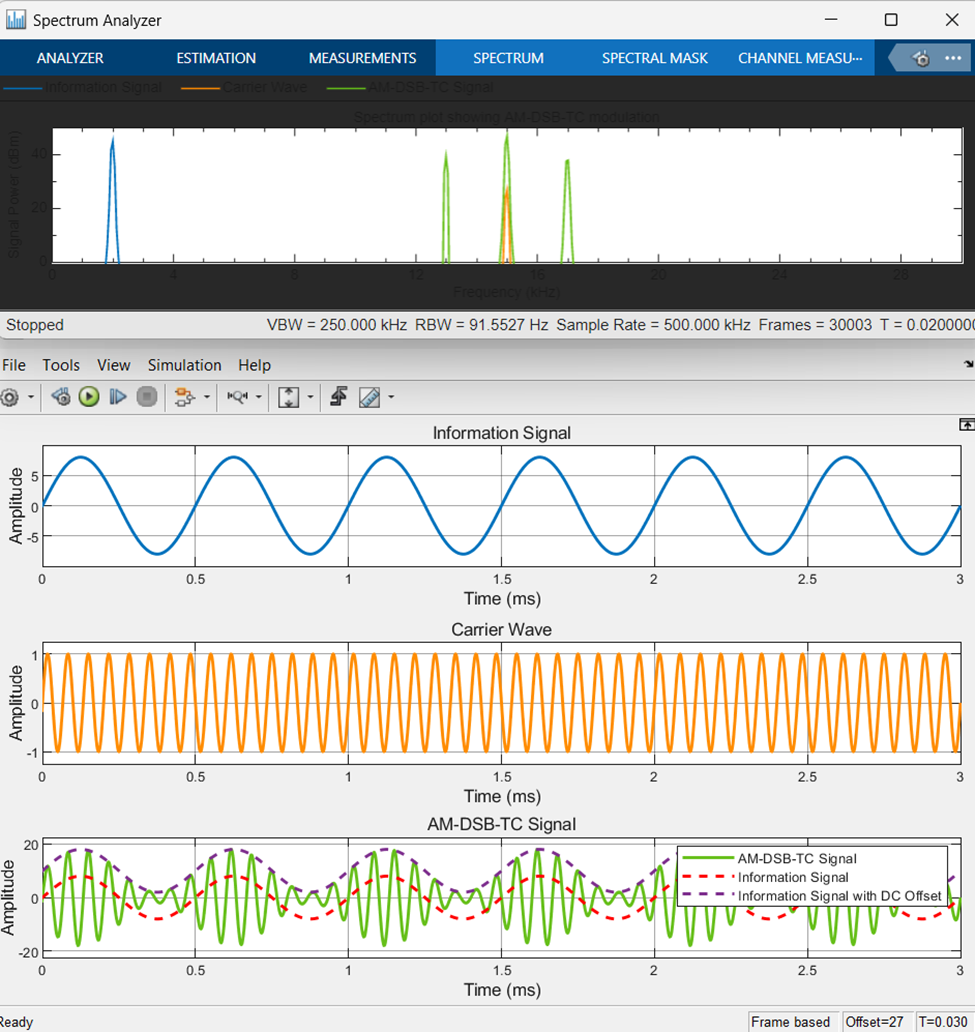

**DSB-TC Sum of Sinusoids**

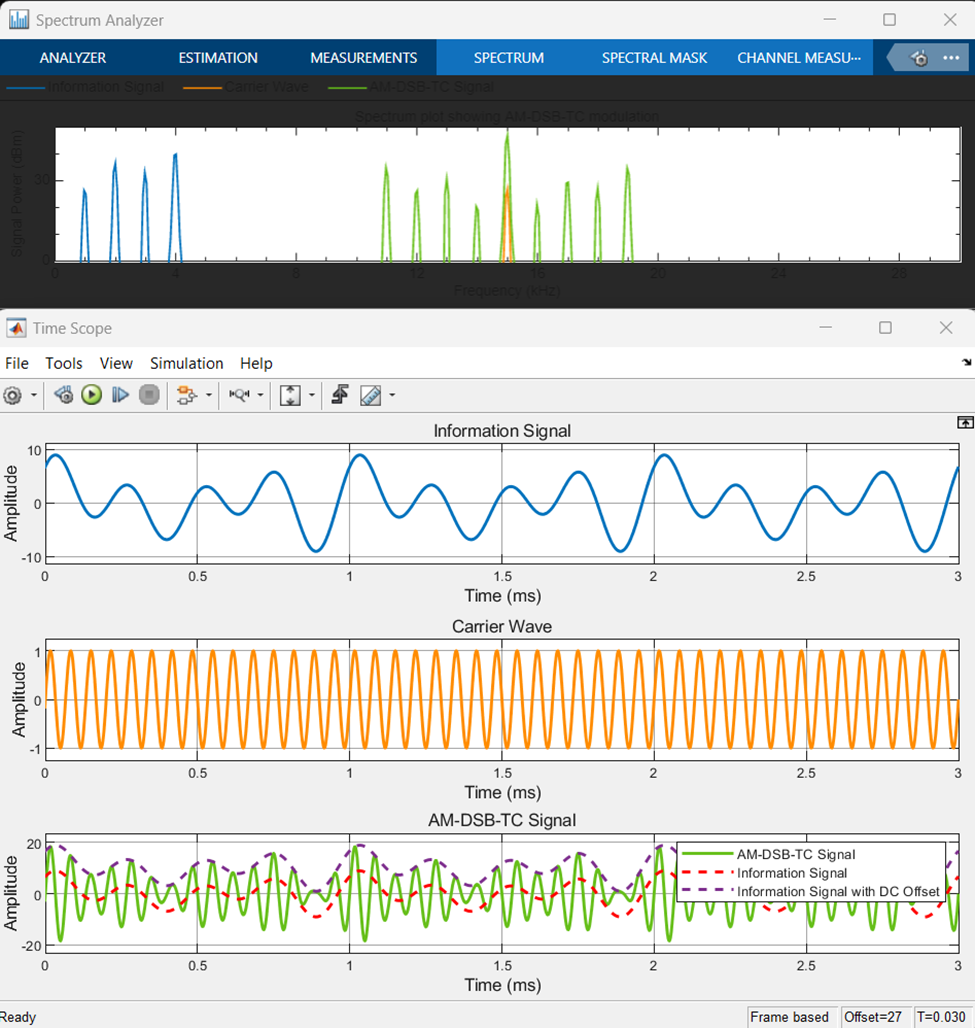

## TASK 2 

**a)**

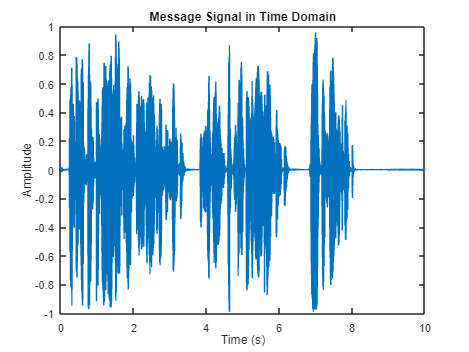

[x, Fs] = audioread('audio1.wav');

t = (0:length(x)-1) / Fs;
figure;
plot(t, x);
xlabel('Time (s)');
ylabel('Amplitude');
title('Message Signal in Time Domain');

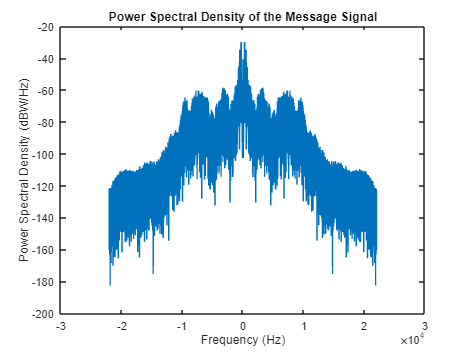


N = length(x);
X = fft(x);
Pxx = (1/(Fs*N)) * abs(X).^2;
f = (-Fs/2):(Fs/N):(Fs/2-Fs/N);
psd_dB = 10*log10(fftshift(Pxx));

figure;
plot(f, psd_dB);
xlabel('Frequency (Hz)');
ylabel('Power Spectral Density (dBW/Hz)');
title('Power Spectral Density of the Message Signal');

**b)**

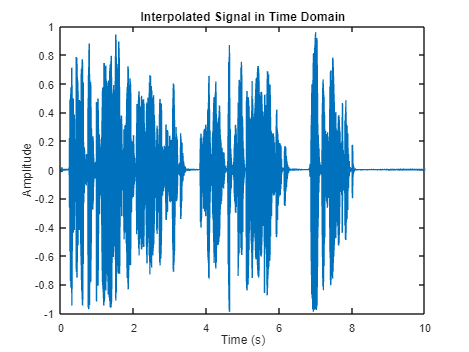

Fs_new = 6 * Fs;
xu = resample(x, Fs_new, Fs);

t_new = (0:length(xu)-1) / Fs_new;
figure;
plot(t_new, xu);
xlabel('Time (s)');
ylabel('Amplitude');
title('Interpolated Signal in Time Domain');

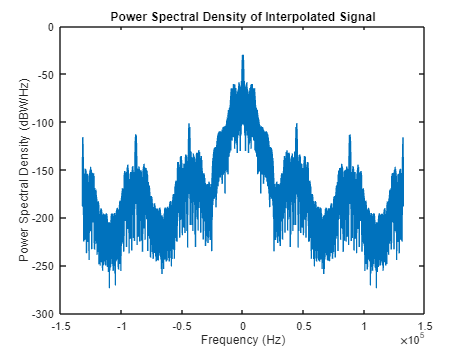


N_new = length(xu);
Xu = fft(xu);
Pxxu = (1/(Fs_new*N_new)) * abs(Xu).^2;
f_new = (-Fs_new/2):(Fs_new/N_new):(Fs_new/2-Fs_new/N_new);
psd_dB_new = 10*log10(fftshift(Pxxu));

figure;
plot(f_new, psd_dB_new);
xlabel('Frequency (Hz)');
ylabel('Power Spectral Density (dBW/Hz)');
title('Power Spectral Density of Interpolated Signal');

**c)**

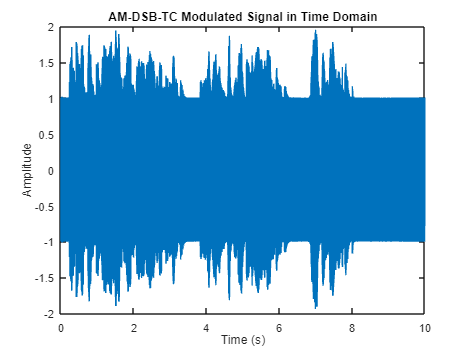

% AM-DSB-TC Modulation parameters
fc = 105e3; % Carrier frequency in Hz

% Modulate the signal
xAM = modulate(xu,fc,Fs_new,'amdsb-tc',-1);

% Plot the modulated signal in the time domain
figure;
plot(t_new, xAM);
xlabel('Time (s)');
ylabel('Amplitude');
title('AM-DSB-TC Modulated Signal in Time Domain');

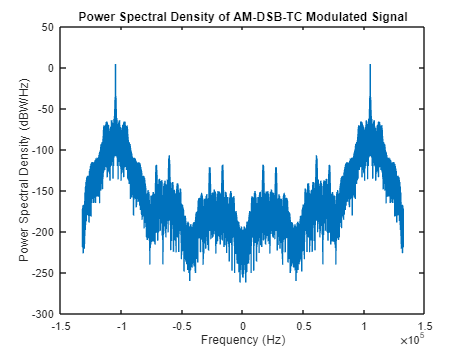


% Calculate and plot the Power Spectral Density (PSD) in dBW/Hz
N_new = length(xAM);
XAM = fft(xAM);
PxxAM = (1/(Fs_new*N_new)) * abs(XAM).^2;
f_new = (-Fs_new/2):(Fs_new/N_new):(Fs_new/2-Fs_new/N_new);
psd_dB_AM = 10*log10(fftshift(PxxAM));

figure;
plot(f_new, psd_dB_AM);
xlabel('Frequency (Hz)');
ylabel('Power Spectral Density (dBW/Hz)');
title('Power Spectral Density of AM-DSB-TC Modulated Signal');

**d)**

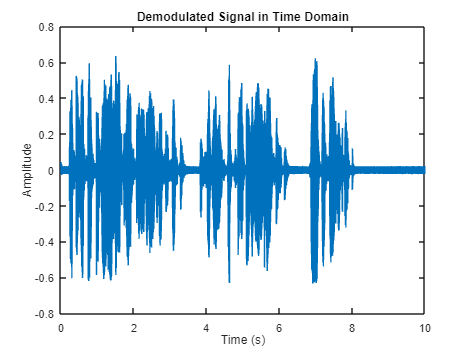

env_signal = abs(xAM);

Fs_downsampled = Fs_new / 6;
env_signal_downsampled = downsample(env_signal, 6);
env_signal_downsampled = env_signal_downsampled - mean(env_signal_downsampled);

cutoff_freq = 5e3;
order = 50;
[b, a] = fir1(order, cutoff_freq*2/Fs_downsampled, 'low');
y_dem = filter(b, a, env_signal_downsampled);

t_downsampled = (0:length(y_dem)-1) / Fs_downsampled;
figure;
plot(t_downsampled, y_dem);
xlabel('Time (s)');
ylabel('Amplitude');
title('Demodulated Signal in Time Domain');

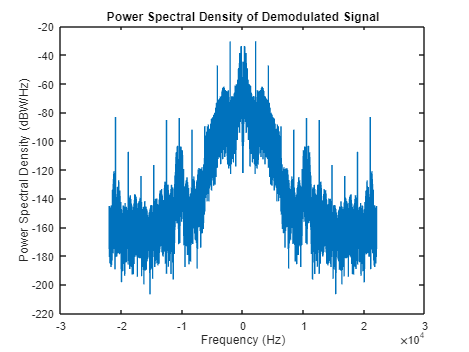


N_dem = length(y_dem);
Y_dem = fft(y_dem);
Pyy_dem = (1/(Fs_downsampled*N_dem)) * abs(Y_dem).^2;
f_dem = (-Fs_downsampled/2):(Fs_downsampled/N_dem):(Fs_downsampled/2-Fs_downsampled/N_dem);
psd_dB_dem = 10*log10(fftshift(Pyy_dem));

figure;
plot(f_dem, psd_dB_dem);
xlabel('Frequency (Hz)');
ylabel('Power Spectral Density (dBW/Hz)');
title('Power Spectral Density of Demodulated Signal');

**e)**

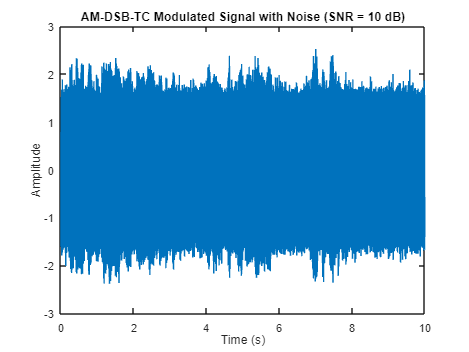

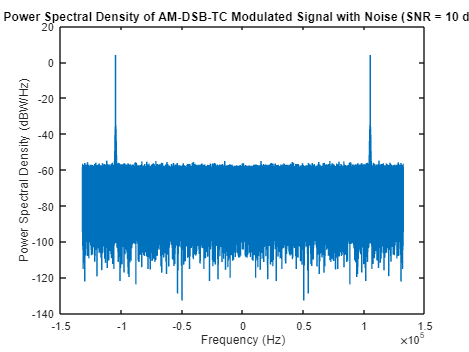

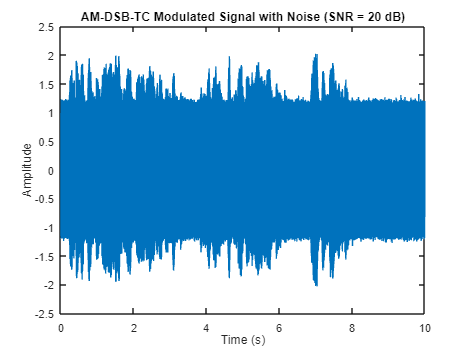

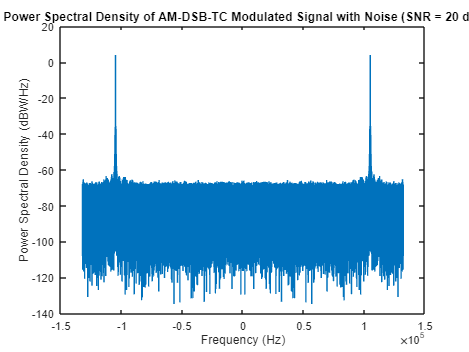

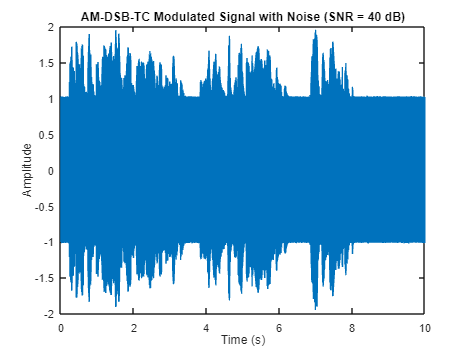

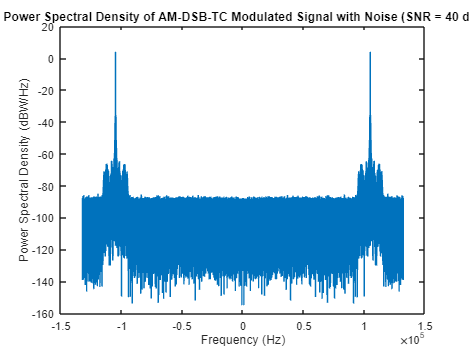

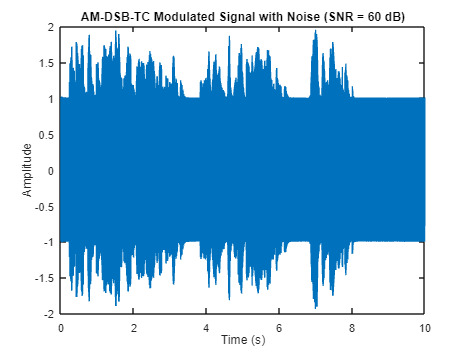

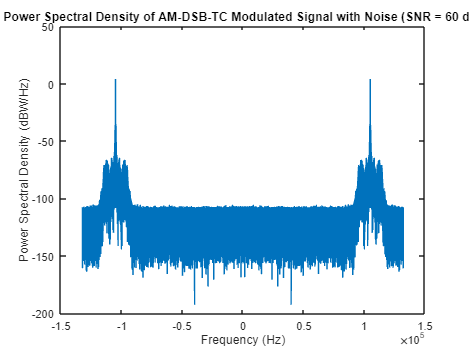

% Signal-to-noise ratios (SNRs) in dB
SNRs = [10, 20, 40, 60];

% Generate AWGN and add it to the modulated signal
xAM_with_noise = cell(1, length(SNRs));
for i = 1:length(SNRs)
    % Calculate noise power
    SNR_linear = 10^(SNRs(i) / 10);
    noise_power = var(xAM) / SNR_linear;
    
    % Generate AWGN
    eta = sqrt(noise_power) * randn(size(xAM));
    
    % Add noise to the modulated signal
    xAM_with_noise{i} = xAM + eta;
end

% Plot the modulated signal with noise for each SNR level
for i = 1:length(SNRs)
    % Plot the modulated signal with noise in the time domain
    figure;
    plot(t_new, xAM_with_noise{i});
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(['AM-DSB-TC Modulated Signal with Noise (SNR = ', num2str(SNRs(i)), ' dB)']);
    
    % Calculate and plot the Power Spectral Density (PSD) in dBW/Hz
    N = length(xAM_with_noise{i});
    X = fft(xAM_with_noise{i});
    Pxx = (1/(Fs_new*N)) * abs(X).^2;
    f = (-Fs_new/2):(Fs_new/N):(Fs_new/2-Fs_new/N);
    psd_dB = 10*log10(fftshift(Pxx));
    
    figure;
    plot(f, psd_dB);
    xlabel('Frequency (Hz)');
    ylabel('Power Spectral Density (dBW/Hz)');
    title(['Power Spectral Density of AM-DSB-TC Modulated Signal with Noise (SNR = ', num2str(SNRs(i)), ' dB)']);
end

**f)**

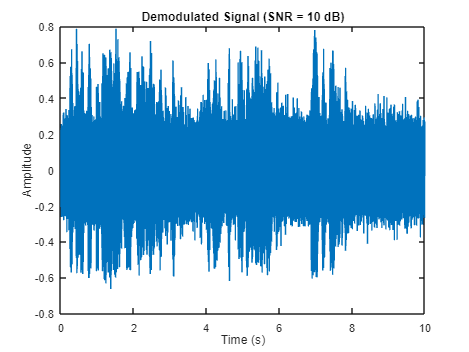

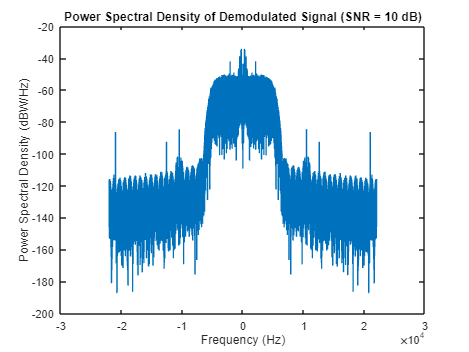

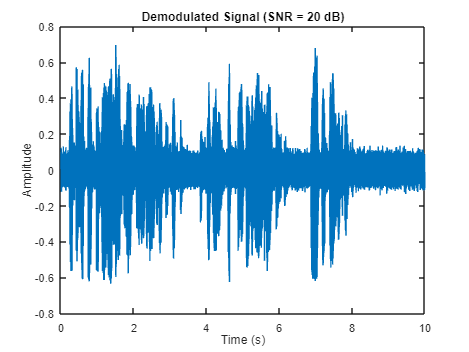

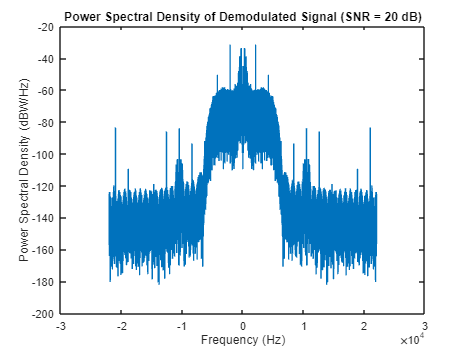

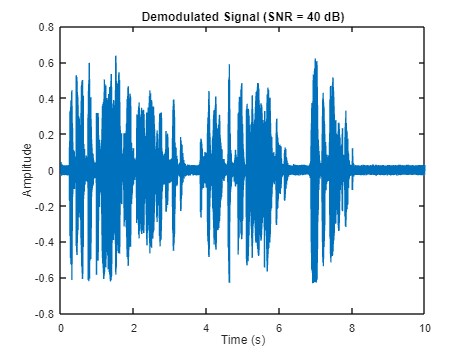

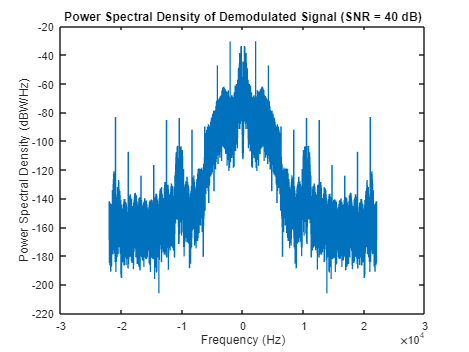

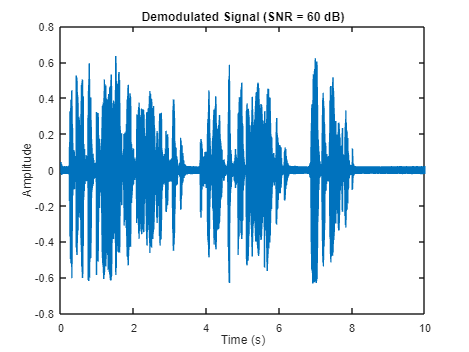

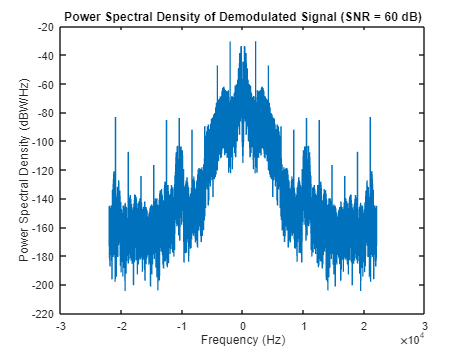

% Parameters for optimized envelope detection
cutoff_freq = 5e3; % Cutoff frequency in Hz
order = 50; % Filter order

% Demodulate the received signals with noise for each SNR level
y_dem = cell(1, length(SNRs));
for i = 1:length(SNRs)
    % Demodulate xAM_with_noise{i} using optimized envelope detection

    % 1. Take the magnitude of xAM_with_noise{i}
    env_signal = abs(xAM_with_noise{i});

    % 2. Downsample by 6 times
    Fs_downsampled = Fs_new / 6;
    env_signal_downsampled = downsample(env_signal, 6);

    % 3. Remove the DC bias
    env_signal_downsampled = env_signal_downsampled - mean(env_signal_downsampled);

    % 4. Apply a lowpass filter to obtain ydem(t)
    [b, a] = fir1(order, cutoff_freq*2/Fs_downsampled, 'low'); % Design FIR filter
    y_dem{i} = filter(b, a, env_signal_downsampled);
end

% Plot the demodulated signals and their PSDs for each SNR level
for i = 1:length(SNRs)
    % Plot the demodulated signal in the time domain
    t_downsampled = (0:length(y_dem{i})-1) / Fs_downsampled;
    figure;
    plot(t_downsampled, y_dem{i});
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(['Demodulated Signal (SNR = ', num2str(SNRs(i)), ' dB)']);

    % Calculate and plot the Power Spectral Density (PSD) in dBW/Hz
    N_dem = length(y_dem{i});
    Y_dem = fft(y_dem{i});
    Pyy_dem = (1/(Fs_downsampled*N_dem)) * abs(Y_dem).^2;
    f_dem = (-Fs_downsampled/2):(Fs_downsampled/N_dem):(Fs_downsampled/2-Fs_downsampled/N_dem);
    psd_dB_dem = 10*log10(fftshift(Pyy_dem));

    figure;
    plot(f_dem, psd_dB_dem);
    xlabel('Frequency (Hz)');
    ylabel('Power Spectral Density (dBW/Hz)');
    title(['Power Spectral Density of Demodulated Signal (SNR = ', num2str(SNRs(i)), ' dB)']);
end

## TASK 3

**a)**

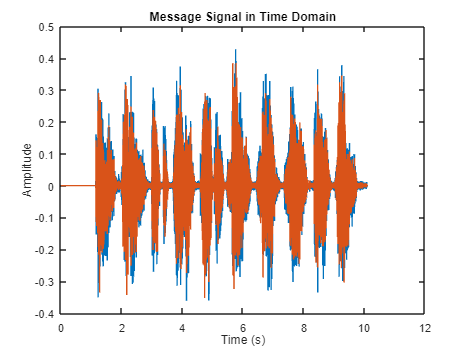

[x, Fs] = audioread('audio2.mp3');
t = (0:length(x)-1) / Fs;
figure;
plot(t, x);
xlabel('Time (s)');
ylabel('Amplitude');
title('Message Signal in Time Domain');

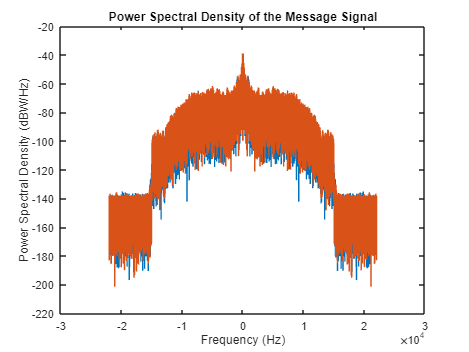

N = length(x);
X = fft(x);
Pxx = (1/(Fs*N)) * abs(X).^2;
f = (-Fs/2):(Fs/N):(Fs/2-Fs/N);
psd_dB = 10*log10(fftshift(Pxx));

figure;
plot(f, psd_dB);
xlabel('Frequency (Hz)');
ylabel('Power Spectral Density (dBW/Hz)');
title('Power Spectral Density of the Message Signal');

**b)**

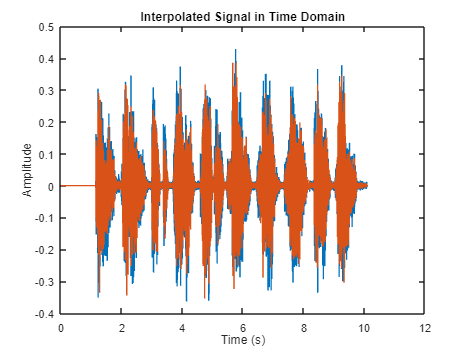


Fs_new = 6 * Fs;
xu = resample(x, Fs_new, Fs);

t_new = (0:length(xu)-1) / Fs_new;
figure;
plot(t_new, xu);
xlabel('Time (s)');
ylabel('Amplitude');
title('Interpolated Signal in Time Domain');

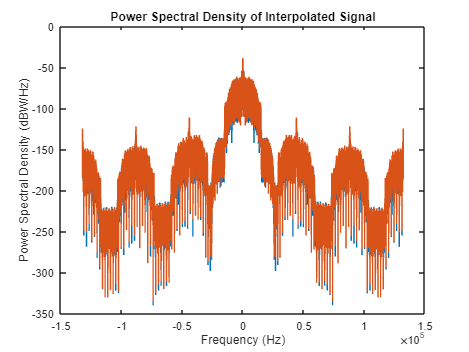

N_new = length(xu);
Xu = fft(xu);
Pxxu = (1/(Fs_new*N_new)) * abs(Xu).^2;
f_new = (-Fs_new/2):(Fs_new/N_new):(Fs_new/2-Fs_new/N_new);
psd_dB_new = 10*log10(fftshift(Pxxu));

figure;
plot(f_new, psd_dB_new);
xlabel('Frequency (Hz)');
ylabel('Power Spectral Density (dBW/Hz)');
title('Power Spectral Density of Interpolated Signal');

**c)**

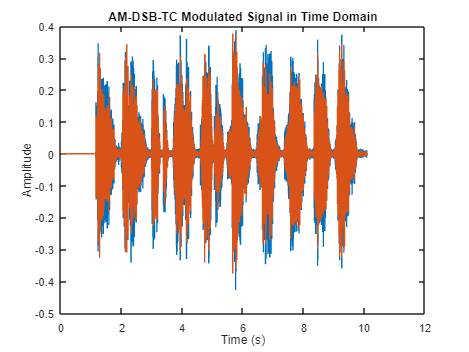

% AM-DSB-SC Modulation parameters
fc = 105e3; % Carrier frequency in Hz

% Modulate the signal
xAM = modulate(xu,fc,Fs_new,'amdsb-sc',-1);

% Plot the modulated signal in the time domain
figure;
plot(t_new, xAM);
xlabel('Time (s)');
ylabel('Amplitude');
title('AM-DSB-TC Modulated Signal in Time Domain');

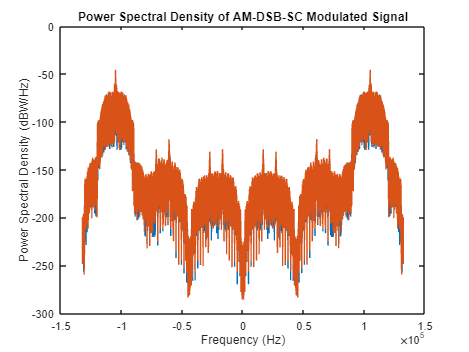

% Calculate and plot the Power Spectral Density (PSD) in dBW/Hz
N_new = length(xAM);
XAM = fft(xAM);
PxxAM = (1/(Fs_new*N_new)) * abs(XAM).^2;
f_new = (-Fs_new/2):(Fs_new/N_new):(Fs_new/2-Fs_new/N_new);
psd_dB_AM = 10*log10(fftshift(PxxAM));

figure;
plot(f_new, psd_dB_AM);
xlabel('Frequency (Hz)');
ylabel('Power Spectral Density (dBW/Hz)');
title('Power Spectral Density of AM-DSB-SC Modulated Signal');